Just reminding you how I use Matlab to solve typical problems like these at the end of Chapter 6. 

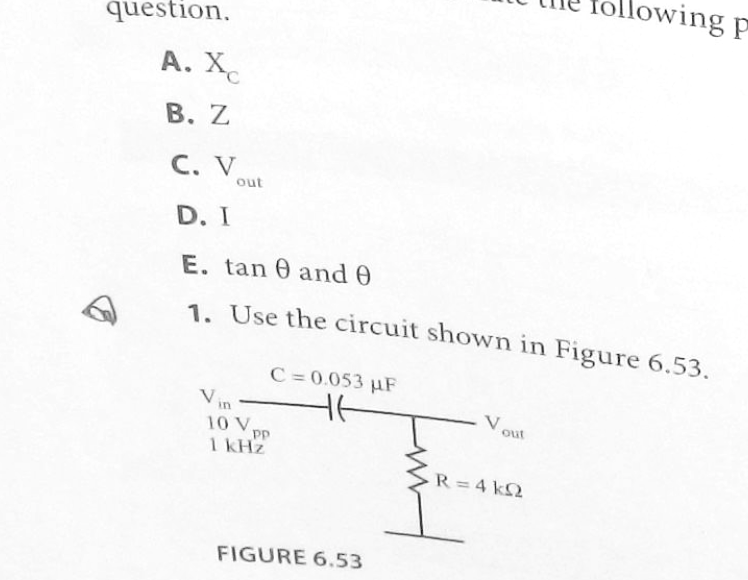

xc = zc(.053e-6,1e3) 

xc = 0.0000e+00 - 3.0029e+03i

abs(xc) % A

ans = 3.0029e+03

z = xc + 4e3 % B

z = 4.0000e+03 - 3.0029e+03i

abs(z)

ans = 5.0018e+03

vout = 10*4e3/z

vout = 6.3955 + 4.8013i

abs(vout) % C

ans = 7.9972

abs(vout)/4e3 % D

ans = 0.0020

theta = angle(vout)*180/pi % E

theta = 36.8967

tan(deg2rad(theta)) % E

ans = 0.7507

tan(angle(vout))

ans = 0.7507

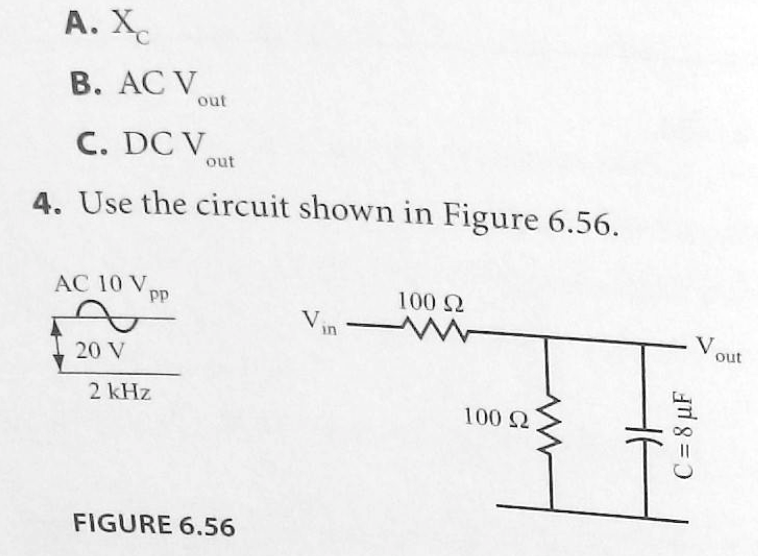

xc = zc(8e-6,2e3)

xc = 0.0000 - 9.9472i

fprintf('A. Xc = %.1f\n',abs(xc))

A. Xc = 9.9


zparallel = zp(100,xc);
vout = 10 * zparallel / (100+zparallel)

vout = 0.1904 - 0.9568i

fprintf('B. AC Vout = %.1f\n', abs(vout))

B. AC Vout = 1.0


fprintf('C. DC Vout = %.1f\n', 10 / 2)

C. DC Vout = 5.0


## .48mH and 1ohm in series with 9ohms driven by  3.13VAC+10Vdc at 1kHz

z = zl(.48e-3,1e3)

z = 0.0000 + 3.0159i

ztot = z+1+9

ztot = 10.0000 + 3.0159i

abs(ztot)

ans = 10.4449

zl(.48e-3,0)

ans = 0

voutac = 3.13*9/ztot

voutac = 2.5821 - 0.7788i

abs(voutac)

ans = 2.6970

theta = angle(voutac)*180/pi

theta = -16.7829